## 初始化

clc;
clear;

## 参数设置

M = 7e3;            %采样点个数
Fs = 15e6;          %采样率
t = 0:1/Fs:1;       %时间间隔

## 文件读取

pathname = 'sw4.xlsx';
wave_data = readmatrix(pathname);
voutp = wave_data(1:M,1);
voutn = wave_data(1:M,2);

## 绘制时域波形图

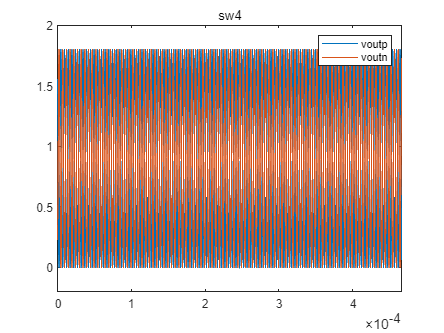

plot(0:1/(15e6):(M - 1)/15e6, voutn(1:M,1));
hold on;
plot(0:1/(15e6):(M - 1)/15e6, voutp(1:M,1));
hold off;
legend(["voutp","voutn"]);
xlim([0 (M-1)/15e6]);
ylim([-0.2 2.0]);
title("sw4");

## 计算voutp的THD、SINAD与SNR

NumHarmonics_P = 5;                                       %保留的谐波个数
[thd_db_P,harmpow_P,harmfreq_P] = thd(voutp,Fs,NumHarmonics_P); %计算thd，单位为dB        
percent_thd_P = 100*(10^(thd_db_P/20));                     %转换为百分比
T_P = table(harmfreq_P,harmpow_P,'VariableNames',{'Frequency','Power'});
disp(T_P);                                                %列举频率与功率值

    Frequency      Power 
    __________    _______

         2e+05    -3.9103
    4.0023e+05    -73.379
    5.9994e+05     -76.39
    7.9929e+05    -100.54
    1.0029e+06    -98.229



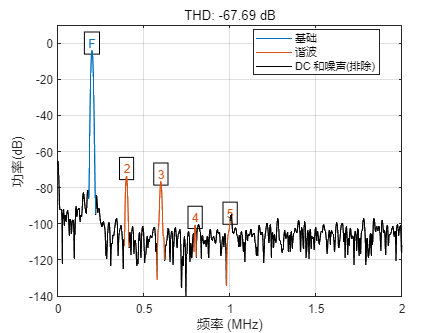

thd(voutp, Fs, NumHarmonics_P);                           %画出谐波图

xlim([0.00 2.00])
ylim([-140 10])

display(percent_thd_P);                                  %打印最终总谐波失真（百分比）

percent_thd_P = 0.0412


SNR_P = snr(voutp,Fs);                                        %计算SNR
SINAD_P = sinad(voutp,Fs);                                    %计算SINAD

fprintf('Voutp_SNR = %.10gdB\n',SNR_P); 

Voutp_SNR = 63.28097927dB


fprintf('Voutp_SINAD = %.10gdB\n',SINAD_P); 

Voutp_SINAD = 61.95188091dB


## 计算voutn的THD、SINAD与SNR

NumHarmonics_N = 5;                                       %保留的谐波个数
[thd_db_N,harmpow_N,harmfreq_N] = thd(voutn,Fs,NumHarmonics_N); %计算thd，单位为dB        
percent_thd_N = 100*(10^(thd_db_N/20));                     %转换为百分比
T_N = table(harmfreq_N,harmpow_N,'VariableNames',{'Frequency','Power'});
disp(T_N);                                                %列举频率与功率值

    Frequency      Power 
    __________    _______

         2e+05    -3.9009
    4.0009e+05    -72.943
    6.0017e+05    -76.553
    7.9953e+05    -100.79
    1.0029e+06    -99.113



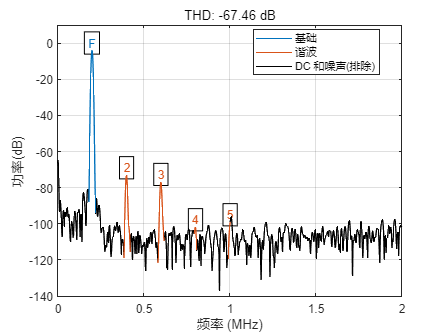

thd(voutn, Fs, NumHarmonics_N);                           %画出谐波图

xlim([0.00 2.00])
ylim([-140 10])

display(percent_thd_N);                                  %打印最终总谐波失真（百分比）

percent_thd_N = 0.0424


SNR_N = snr(voutn,Fs);                                        %计算SNR
SINAD_N = sinad(voutn,Fs);                                    %计算SINAD

fprintf('Voutn_SNR = %.10gdB\n',SNR_N); 

Voutn_SNR = 62.75658906dB


fprintf('Voutn_SINAD = %.10gdB\n',SINAD_N); 

Voutn_SINAD = 61.5029324dB
